# Network Intrusion Detector

clear;
clc;

a) load dataset

dataset2 = load("cw_dataset_2class.txt");


% dataset2 = normalize(dataset2)

% shuffle data
selectRows = size(dataset2,1);
shuffle = randperm(selectRows);
shuffledDataset = dataset2(shuffle, :);

% transpose
shuffledDataset = shuffledDataset';
% [trainingDataset, validationDataset, testingDataset] = dividerand(dataset2, 2/3, 0, 1/3);
[trainingDataset, validationDataset, testingDataset] = dividerand(shuffledDataset, 2/3, 0, 1/3);
% trainingDataset = trainingDataset';
% validationDataset = validationDataset';
% testingDataset = testingDataset';

b) Create training data, training target, testing data and testing target. 

%get preprocessing data from columns 1-41 
trainingData = trainingDataset(1:41,:);
% get target data from columns 42
trainingTargetData = trainingDataset(42,:);

% get preprocessing data from columns 1-41 
testingData = testingDataset(1:41,:);
% get target data from columns 42 
testingTarget = testingDataset(42,:);

c) Select Pattern Recognition Neural Network (patternnet)

% Define the number of neurons
numOfNeurons = 10;
%select pattern net
net = patternnet(numOfNeurons);

d) Define the number of neurons of the neural network (assume only one hidden layer), define the neural network parameters, e.g. epochs, error goal, and learning rate.

% Define epoch, error goal and learning rate
epochs = 50;
errorGoal = 0.001;
learningRate = 0.1;

% Update parameters
net.trainParam.epochs = epochs;
net.trainParam.goal = errorGoal;
net.trainParam.lr = learningRate;
%stop testing spit set param to 0 
net.divideParam.testRatio = 0;

e) Train the neural network based on the training dataset created, and view the trained net (similar as Figure 5, input and output numbers are just for illustration).

% train dataset 
[net, tr] = train(net, trainingData, trainingTargetData);
view(net)
plotperform(tr);%plot performance graph

f) Test the trained net using testing dataset and evaluate its performance (e.g. classifier accuracy and recall rate). You may run several times for training and testing to get an average performance value. Why does each run has different results?

% array of results
% cross etropy
cEntropys = [];
% Accuracy
accuracies = [];
% Recall Rate
recallRates = [];
% precision
precisions = [];

% run 10 times to gather 10 results for each performance metric 
for it = 1:10
    % Define the number of neurons
    numOfNeurons = 10;
    %select pattern net
    net = patternnet(numOfNeurons);
    % Define epoch, error goal and learning rate
    net.trainParam.epochs = 50;
    net.trainParam.goal = 0.001;
    net.trainParam.lr = 0.1;
    %stop testing spit set param to 0 
    net.divideParam.testRatio = 0;
    % train dataset 
    [net] = train(net, trainingData, trainingTargetData);

    % run neural network on testing data
    predictedData = net(testingData);
    % get performance of the neural network on the testing data
    perp = perform(net, testingTarget, predictedData);
    % display performance value (cross entropy)
%     disp("Cross etropy:" + perp)
    % add cross entropy value to array of cross entropies
    cEntropys(end+1) = perp;
    
    %round predicted array
    predictedRounded = round(predictedData);
    
    % Accuracy
    numCorrectProdictions = 0;
    % loop through both arrays
    for i = 1:size(predictedRounded,2)
        % compare target against predicted
        if(testingTarget(i) == predictedRounded(i))
            % count correct prediction
            numCorrectProdictions = numCorrectProdictions + 1;
        end
    end
    
    %calculate accuracy 
    accuracy = numCorrectProdictions/ size(predictedRounded,2) * 100;
%     disp("Accuracy: " + accuracy + "%")
    % add accuracy value to array of accuracies
    accuracies(end + 1) = accuracy;

    % recall rate
    totalTruePositive = 0;
    totalActualPositive = 0;
    % loop through both arrays
    for i = 1:size(predictedRounded,2)
        % check if true positive
        if(predictedRounded(i) == 1 && predictedRounded(i) == testingTarget(i))
            % count number of true positives
            totalTruePositive = totalTruePositive + 1;
        end
        % check if actual positive
        if(testingTarget(i) == 1)
            % count number of actual positives
            totalActualPositive = totalActualPositive + 1;
        end
    end
    % calculate Recall rate
    recallRate = totalTruePositive / totalActualPositive * 100;
%     disp("Recall Rate: " + recallRate + "%")
    % add Recall rate to array of recall rates
    recallRates(end + 1) = recallRate;
    
    % Precision 
    totalTruePositive = 0;
    totalPredictedPositives = 0;
    for i = 1:size(predictedRounded,2)
        % check if true positive
        if(predictedRounded(i) == 1 && predictedRounded(i) == testingTarget(i))
            % count true positives
            totalTruePositive = totalTruePositive + 1;
        end
        % check if predicted positive
        if(predictedRounded(i) == 1)
            % count predicted positives
            totalPredictedPositives = totalPredictedPositives + 1;
        end
    end
    %calculate Precision
    precision = totalTruePositive/totalPredictedPositives * 100;
%     disp("Precision: " + precision + "%")
    % add precision to array of precisions
    precisions(end + 1) = precision;

end

cEntropys

cEntropys =     0.0262    0.0306    0.0275    0.0280    0.0214    0.0339    0.0241    0.0308    0.0299    0.0230


accuracies

accuracies =    99.5556   99.5556   99.3333   99.5556   99.4444   99.5556   99.5556   99.4444   99.2222   99.5556


recallRates

recallRates =    99.2611   99.2611   98.7685   99.2611   99.0148   99.2611   99.2611   99.0148   99.0148   99.2611


precisions

precisions =    99.7525   99.7525   99.7512   99.7525   99.7519   99.7525   99.7525   99.7519   99.2593   99.7525


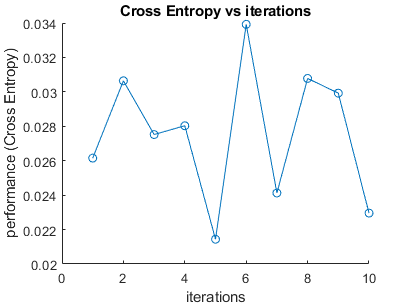


% plot performance metrics 
% cross entropy
figure
hold on
xlabel('iterations')
ylabel('performance (Cross Entropy)')
plot(cEntropys,"o-")
title('Cross Entropy vs iterations')
hold off

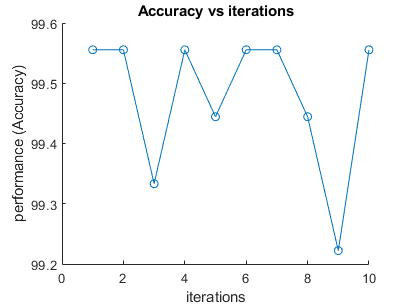

% accuracy
figure
hold on
xlabel('iterations')
ylabel('performance (Accuracy)')
plot(accuracies,"o-")
title('Accuracy vs iterations')
hold off

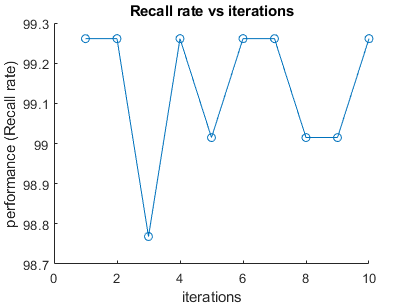

% Recall rate
figure
hold on
xlabel('iterations')
ylabel('performance (Recall rate)')
plot(recallRates,"o-")
title('Recall rate vs iterations')
hold off

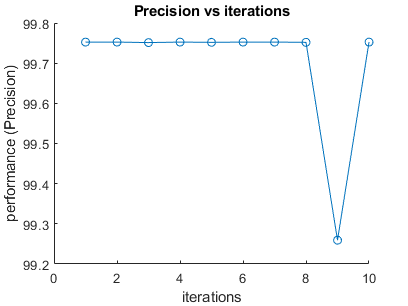

% Precision
figure
hold on
xlabel('iterations')
ylabel('performance (Precision)')
plot(precisions,"o-")
title('Precision vs iterations')
hold off


% average cross entropy
aveCEntropys = sum(cEntropys)/size(cEntropys,2);
disp("Average Cross Entropy: " + aveCEntropys)

Average Cross Entropy: 0.02755


% average Accuracy
aveAccuracy = sum(accuracies)/size(accuracies,2);
disp("Average Accuracy: " + aveAccuracy + "%")

Average Accuracy: 99.4778%


% average Recall rate
aveRecallRate = sum(recallRates)/size(recallRates,2);
disp("Average Recall rate: " + aveRecallRate + "%")

Average Recall rate: 99.1379%


% average Precision
avePrecision = sum(precisions)/size(precisions,2);
disp("Average Precision: " + avePrecision + "%")

Average Precision: 99.7029%




%confusion matrix
[c,cm,ind,per]= confusion(testingTarget, predictedData);
cm

cm =    493     1
     3   403


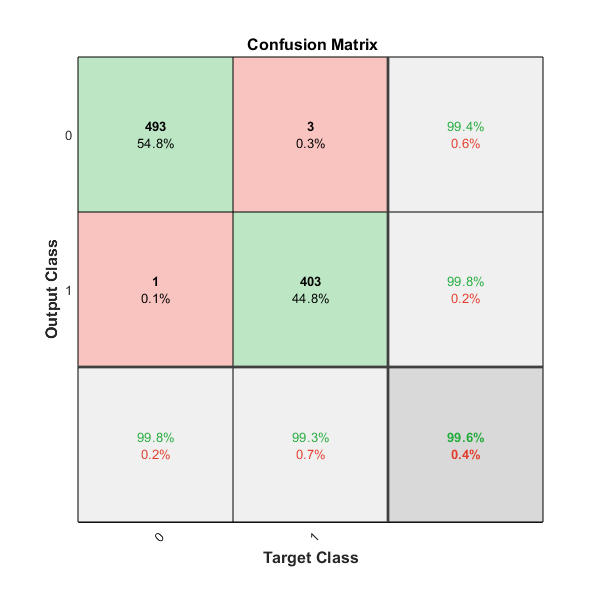

plotconfusion(testingTarget,predictedData)

g) Explore how neural network parameters (e.g. learning rate) and the number of neurons affect the performance of classifier. Explain what are normal stopping criteria for training.

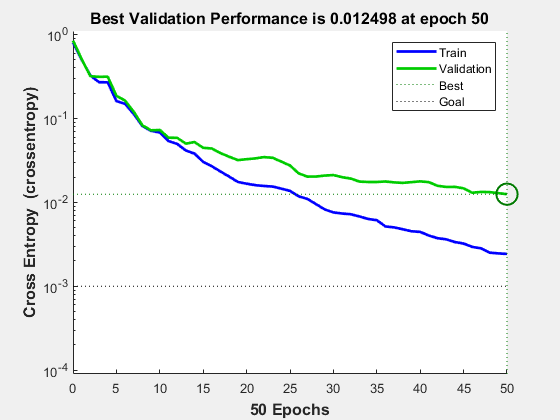

neuronPerformances=[];
for numOfNeurons = 1:10
    %select pattern net
    net = patternnet(numOfNeurons);
    
    % Define epoch, error goal and learning rate
    net.trainParam.epochs = 50;
    net.trainParam.goal = 0.001;
    net.trainParam.lr = 0.1;
    %stop testing spit set param to 0 
    net.divideParam.testRatio = 0;

    % train network
    [net] = train(net, trainingData, trainingTargetData);
    
    % get performance on test data
    predictedData = net(testingData);
    perf = perform(net, testingTarget, predictedData);

    % add to neuron performance array
    neuronPerformances(end + 1) = perf;
end
% reset number of neurons to 10
numOfNeurons = 10;

%select pattern net
net = patternnet(numOfNeurons);

% Define epochs and error goal
net.trainParam.epochs = 50;
net.trainParam.goal = 0.001;
%stop testing spit set param to 0 
net.divideParam.testRatio = 0;

%change learning rate 
learningRatePerformance = [];
% learningRates = [1,0.5,0.1,0.05,0.01,0.005,0.001,0.0005,0.0001, 0.00005];
learningRates = [1,0.75,0.5,0.25,0.1,0.075,0.05,0.025,0.01,0.0075];
for it = 1:10
    
    % Define learning rate
    net.trainParam.lr = learningRates(it);

    %train network
    [net] = train(net, trainingData, trainingTargetData);

    % get performance on test data
    predictedData = net(testingData);
    perf = perform(net, testingTarget, predictedData);

    % add to learning rate performance array
    learningRatePerformance(end + 1) = perf;
end

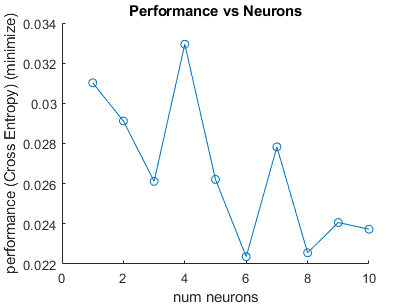

% learningRatePerformance
% learningRates

% plot perfromance (Cross entropy) graphs
figure
hold on
xlabel('num neurons')
ylabel('performance (Cross Entropy) (minimize)')
plot(neuronPerformances,"o-")
title('Performance vs Neurons')
hold off

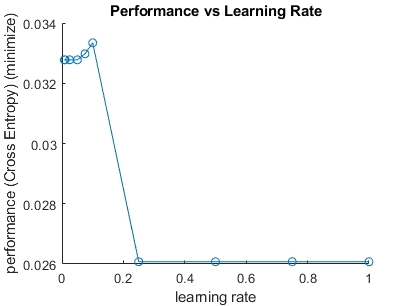


figure
hold on
xlabel('learning rate')
ylabel('performance (Cross Entropy) (minimize)')
plot(learningRates,learningRatePerformance,"o-")
title('Performance vs Learning Rate')
hold off

h) After completion of intrusion detector for just two classes (‘normal’ and ‘attack’), you now decide to further develop intrusion detection classifier for 3 classes (i.e. ‘normal’, DoS and probing attack), and 5 classes (i.e. ‘normal’, ‘smurf’, ‘neptune, ‘satan’ and ‘ipsweep’). What performance can you get for the intrusion detection classifier?

% 3 classes
dataset3 = load("cw_dataset_3class.txt");

% shuffle data
selectRows = size(dataset3,1);
shuffle = randperm(selectRows);
shuffledDataset = dataset3(shuffle, :);
%transpose data
shuffledDataset = shuffledDataset';
[trainingDataset, validationDataset, testingDataset] = dividerand(shuffledDataset, 2/3, 0, 1/3);

trainingData = trainingDataset(1:41,:);
trainingTargetData = trainingDataset(42:44,:);

testingData = testingDataset(1:41,:);
testingTarget = testingDataset(42:44,:);

% Define the number of neurons
numOfNeurons = 10;

%select pattern net
net = patternnet(numOfNeurons);

% Define epoch, error goal and learning rate
epochs = 50;
errorGoal = 0.001;
learningRate = 0.1;

net.trainParam.epochs = epochs;
net.trainParam.goal = errorGoal;
net.trainParam.lr = learningRate;
%stop testing spit set param to 0 
net.divideParam.testRatio = 0;

[net, tr] = train(net, trainingData, trainingTargetData);
view(net)

predictedData = net(testingData);
perp = perform(net, testingTarget, predictedData);
disp("3 class performance: "+ perp);

3 class performance: 0.0075497



[c,cm,ind,per] = confusion(testingTarget, predictedData);
cm

cm =    518     3     0
     4   276     0
     0     0    99


% truePositives = cm(1,1)
% trueNegatives = cm(2,2)
% falseNegatives = cm(2,1)
% falsePositives = cm(1,2)

% class 1 True positive, false negative, false positive, true negative
class1TruePositives = cm(1,1);
class1FalseNegatives = sum(cm(1,:)) - class1TruePositives;
class1FalsePositives = sum(cm(:,1)) - class1TruePositives;
class1TrueNegatives = sum(sum(cm(2:3,2:3)));

% class 2 True positive, false negative, false positive, true negative
class2TruePositives = cm(2,2);
class2FalseNegatives = sum(cm(2,:)) - class2TruePositives;
class2FalsePositives = sum(cm(:,2)) - class2TruePositives;
class2TrueNegatives = sum(sum(cm(3:3,3:3))) + sum(cm(1,2:3)) + sum(cm(:,1));

% class 3 True positive, false negative, false positive, true negative
class3TruePositives = cm(3,3);
class3FalseNegatives = sum(cm(3,:)) - class3TruePositives;
class3FalsePositives = sum(cm(:,3)) - class3TruePositives;
class3TrueNegatives = sum(sum(cm(:,:))) - class3FalsePositives - class3FalseNegatives - class3TruePositives;

disp("3 Classification performance metrics")

3 Classification performance metrics


% accuracy
accuracy1 = (class1TruePositives+class1TrueNegatives)/size(predictedData,2)*100;
disp("Class 1 Accuracy: " + accuracy1 + "%")

Class 1 Accuracy: 99.2222%


% precision
precision1 = class1TruePositives/(class1TruePositives+class1FalsePositives)*100;
disp("Class 1 Precision: " + precision1 + "%")

Class 1 Precision: 99.2337%


% recall rate
recallRate1 = class1TruePositives/(class1TruePositives+class1FalseNegatives)*100;
disp("Class 1 Recall Rate: " + recallRate1 + "%")

Class 1 Recall Rate: 99.4242%



% Disp("Class 2")
% accuracy
accuracy2 = (class2TruePositives+class2TrueNegatives)/size(predictedData,2)*100;
disp("Class 2 Accuracy: " + accuracy2 + "%")

Class 2 Accuracy: 100%


% precision
precision2 = class2TruePositives/(class2TruePositives+class2FalsePositives)*100;
disp("Class 2 Precision: " + precision2 + "%")

Class 2 Precision: 98.9247%


% recall rate
recallRate2 = class2TruePositives/(class2TruePositives+class2FalseNegatives)*100;
disp("Class 2 Recall Rate: " + recallRate2 + "%")

Class 2 Recall Rate: 98.5714%



% Disp("Class 3")
% accuracy
accuracy3 = (class3TruePositives+class3TrueNegatives)/size(predictedData,2)*100;
disp("Class 3 Accuracy: " + accuracy3 + "%")

Class 3 Accuracy: 100%


% precision
precision3 = class3TruePositives/(class3TruePositives+class3FalsePositives)*100;
disp("Class 3 Precision: " + precision3 + "%")

Class 3 Precision: 100%


% recall rate
recallRate3 = class3TruePositives/(class3TruePositives+class3FalseNegatives)*100;
disp("Class 3 Recall Rate: " + recallRate3 + "%")

Class 3 Recall Rate: 100%



% get the average metrics of 3 classes
disp("Average Accuracy of 3 Classes: " + (accuracy1 + accuracy2 + accuracy3)/3 + "%")

Average Accuracy of 3 Classes: 99.7407%


disp("Average Precision of 3 Classes: " + (precision1 + precision2 + precision3)/3 + "%")

Average Precision of 3 Classes: 99.3861%


disp("Average Recall Rate of 3 Classes: " + (recallRate1 + recallRate2 + recallRate3)/3 + "%")

Average Recall Rate of 3 Classes: 99.3319%


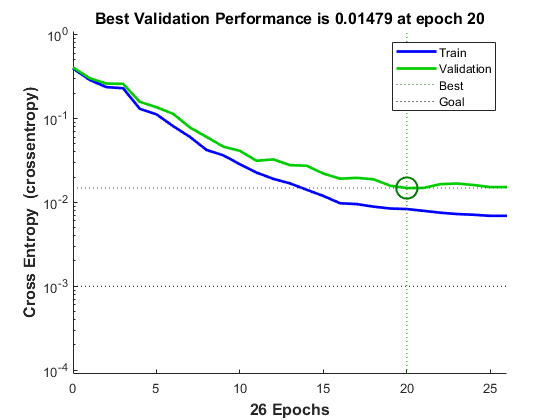

% % accuracy
% accuracy = (truePositives+trueNegatives)/size(predictedData,2)*100;
% disp("Accuracy: " + accuracy)
% % precision
% precision = truePositives/(truePositives+falsePositives)*100;
% disp("Precision: " + precision)
% % recall rate
% recallRate = truePositives/(truePositives+falseNegatives)*100;
% disp("Recall Rate: " + recallRate)

plotperform(tr);%plot performance graph

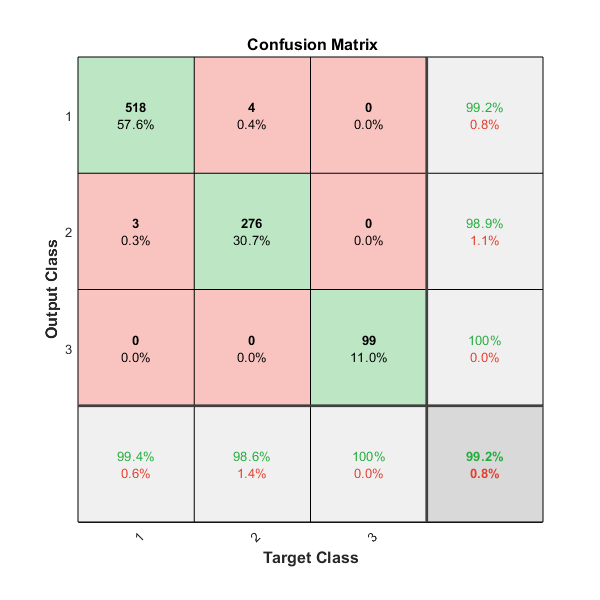

plotconfusion(testingTarget,predictedData)




% 5 classes
dataset5 = load("cw_dataset_5class.txt");

% shuffle data
selectRows = size(dataset5,1);
shuffle = randperm(selectRows);
shuffledDataset = dataset5(shuffle, :);
%transpose data
shuffledDataset = shuffledDataset';
[trainingDataset, validationDataset, testingDataset] = dividerand(shuffledDataset, 2/3, 0, 1/3);

trainingData = trainingDataset(1:41,:);
trainingTargetData = trainingDataset(42:46,:);

testingData = testingDataset(1:41,:);
testingTarget = testingDataset(42:46,:);

% Define the number of neurons
numOfNeurons = 10;

%select pattern net
net = patternnet(numOfNeurons);

% Define epoch, error goal and learning rate
epochs = 50;
errorGoal = 0.001;
learningRate = 0.1;

net.trainParam.epochs = epochs;
net.trainParam.goal = errorGoal;
net.trainParam.lr = learningRate;
%stop testing spit set param to 0 
net.divideParam.testRatio = 0;

[net, tr] = train(net, trainingData, trainingTargetData);
view(net)

predictedData = net(testingData);
perp = perform(net, testingTarget, predictedData);
disp("5 class performance: " + perp);

5 class performance: 0.0069462



[c,cm,ind,per] = confusion(testingTarget, predictedData);
cm

cm =    495     0     0     7     0
     0   103     0     0     0
     0     0    95     0     0
     1     0     0   108     1
     2     0     0     0    88


% truePositives = cm(1,1)
% trueNegatives = cm(2,2)
% falseNegatives = cm(2,1)
% falsePositives = cm(1,2)

% class 1 True positive, false negative, false positive, true negative
class1TruePositives = cm(1,1);
class1FalseNegatives = sum(cm(1,:)) - class1TruePositives;
class1FalsePositives = sum(cm(:,1)) - class1TruePositives;
class1TrueNegatives = sum(sum(cm(2:5,2:5)));

% class 2 True positive, false negative, false positive, true negative
class2TruePositives = cm(2,2);
class2FalseNegatives = sum(cm(2,:)) - class2TruePositives;
class2FalsePositives = sum(cm(:,2)) - class2TruePositives;
class2TrueNegatives = sum(sum(cm(3:5,3:5))) + sum(cm(1,2:5)) + sum(cm(:,1));

% class 3 True positive, false negative, false positive, true negative
class3TruePositives = cm(3,3);
class3FalseNegatives = sum(cm(3,:)) - class3TruePositives;
class3FalsePositives = sum(cm(:,3)) - class3TruePositives;
class3TrueNegatives = sum(sum(cm(:,:))) - class3FalsePositives - class3FalseNegatives - class3TruePositives;

% class 4 True positive, false negative, false positive, true negative
class4TruePositives = cm(4,4);
class4FalseNegatives = sum(cm(4,:)) - class4TruePositives;
class4FalsePositives = sum(cm(:,4)) - class4TruePositives;
class4TrueNegatives = sum(sum(cm(:,:))) - class4FalsePositives - class4FalseNegatives - class4TruePositives;

% class 5 True positive, false negative, false positive, true negative
class5TruePositives = cm(5,5);
class5FalseNegatives = sum(cm(5,:)) - class5TruePositives;
class5FalsePositives = sum(cm(:,5)) - class5TruePositives;
class5TrueNegatives = sum(sum(cm(:,:))) - class5FalsePositives - class5FalseNegatives - class5TruePositives;

disp("5 Classification performance metrics")

5 Classification performance metrics


% accuracy
accuracy1 = (class1TruePositives+class1TrueNegatives)/size(predictedData,2)*100;
disp("Class 1 Accuracy: " + accuracy1 + "%")

Class 1 Accuracy: 98.8889%


% precision
precision1 = class1TruePositives/(class1TruePositives+class1FalsePositives)*100;
disp("Class 1 Precision: " + precision1 + "%")

Class 1 Precision: 99.3976%


% recall rate
recallRate1 = class1TruePositives/(class1TruePositives+class1FalseNegatives)*100;
disp("Class 1 Recall Rate: " + recallRate1 + "%")

Class 1 Recall Rate: 98.6056%



% Disp("Class 2")
% accuracy
accuracy2 = (class2TruePositives+class2TrueNegatives)/size(predictedData,2)*100;
disp("Class 2 Accuracy: " + accuracy2 + "%")

Class 2 Accuracy: 100%


% precision
precision2 = class2TruePositives/(class2TruePositives+class2FalsePositives)*100;
disp("Class 2 Precision: " + precision2 + "%")

Class 2 Precision: 100%


% recall rate
recallRate2 = class2TruePositives/(class2TruePositives+class2FalseNegatives)*100;
disp("Class 2 Recall Rate: " + recallRate2 + "%")

Class 2 Recall Rate: 100%



% Disp("Class 3")
% accuracy
accuracy3 = (class3TruePositives+class3TrueNegatives)/size(predictedData,2)*100;
disp("Class 3 Accuracy: " + accuracy3 + "%")

Class 3 Accuracy: 100%


% precision
precision3 = class3TruePositives/(class3TruePositives+class3FalsePositives)*100;
disp("Class 3 Precision: " + precision3 + "%")

Class 3 Precision: 100%


% recall rate
recallRate3 = class3TruePositives/(class3TruePositives+class3FalseNegatives)*100;
disp("Class 3 Recall Rate: " + recallRate3 + "%")

Class 3 Recall Rate: 100%



% Disp("Class 4")
% accuracy
accuracy4 = (class4TruePositives+class4TrueNegatives)/size(predictedData,2)*100;
disp("Class 4 Accuracy: " + accuracy4 + "%")

Class 4 Accuracy: 99%


% precision
precision4 = class4TruePositives/(class4TruePositives+class4FalsePositives)*100;
disp("Class 4 Precision: " + precision4 + "%")

Class 4 Precision: 93.913%


% recall rate
recallRate4 = class4TruePositives/(class4TruePositives+class4FalseNegatives)*100;
disp("Class 4 Recall Rate: " + recallRate4 + "%")

Class 4 Recall Rate: 98.1818%



% Disp("Class 5")
% accuracy
accuracy5 = (class5TruePositives+class5TrueNegatives)/size(predictedData,2)*100;
disp("Class 5 Accuracy: " + accuracy5 + "%")

Class 5 Accuracy: 99.6667%


% precision
precision5 = class5TruePositives/(class5TruePositives+class5FalsePositives)*100;
disp("Class 5 Precision: " + precision5 + "%")

Class 5 Precision: 98.8764%


% recall rate
recallRate5 = class5TruePositives/(class5TruePositives+class5FalseNegatives)*100;
disp("Class 5 Recall Rate: " + recallRate5 + "%")

Class 5 Recall Rate: 97.7778%



% get the average metrics of 5 classes
disp("Average Accuracy of 5 Classes: " + (accuracy1 + accuracy2 + accuracy3 + accuracy4 + accuracy5)/5 + "%")

Average Accuracy of 5 Classes: 99.5111%


disp("Average Precision of 5 Classes: " + (precision1 + precision2 + precision3 + precision4 + precision5)/5 + "%")

Average Precision of 5 Classes: 98.4374%


disp("Average Recall Rate of 5 Classes: " + (recallRate1 + recallRate2 + recallRate3 + recallRate4 + recallRate5)/5 + "%")

Average Recall Rate of 5 Classes: 98.913%


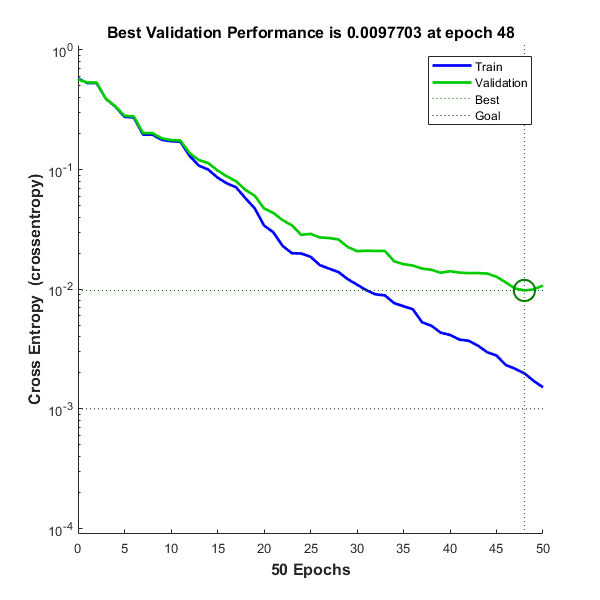


% % accuracy
% accuracy = (truePositives+trueNegatives)/size(predictedData,2)*100;
% disp("Accuracy: " + accuracy)
% % precision
% precision = truePositives/(truePositives+falsePositives)*100;
% disp("Precision: " + precision)
% % recall rate
% recallRate = truePositives/(truePositives+falseNegatives)*100;
% disp("Recall Rate: " + recallRate)

plotperform(tr);%plot performance graph

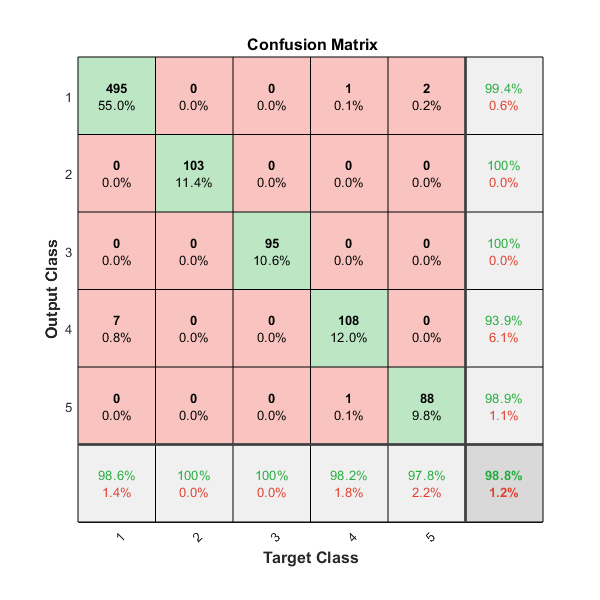


plotconfusion(testingTarget,predictedData)